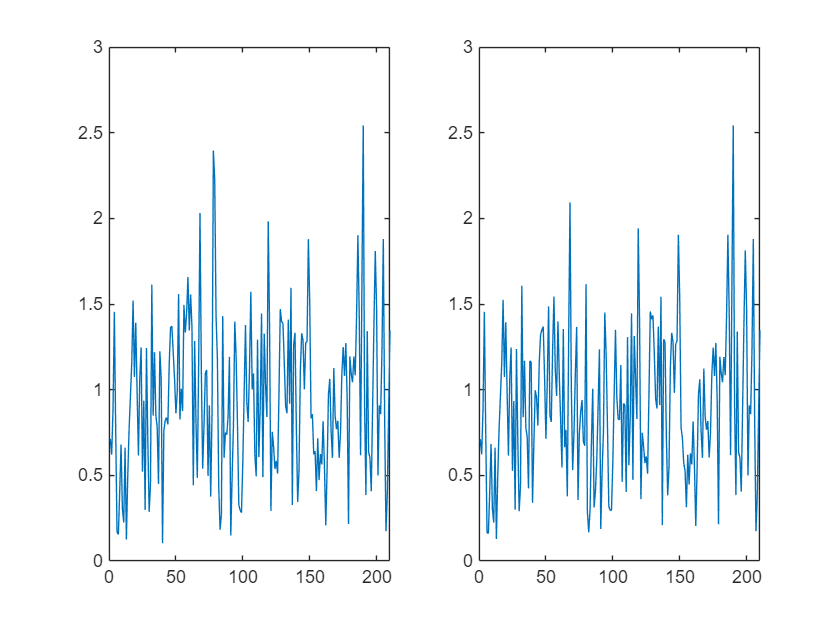

clc; close all; clear;
datapath_tg_1 = "../data/Target/1Z.mat";
datapath_tg_2 = "../data/Target/2F.mat";
datapath_cl_1 = "../data/Clutter/XB.mat";
datapath_cl_2 = "../data/Clutter/XL.mat";

HRRP_tg_1 = load(datapath_tg_1).HRRP_020;
HRRP_tg_2 = load(datapath_tg_2).HRRP_020;
HRRP_cl_1 = load(datapath_cl_1).Cl_data;
HRRP_cl_2 = load(datapath_cl_2).Cl_data;
tg1_hh=squeeze(HRRP_tg_1.hh(:,1)');
tg1_hv=squeeze(HRRP_tg_1.hv(:,1)');
tg1_vh=squeeze(HRRP_tg_1.vh(:,1)');
tg1_vv=squeeze(HRRP_tg_1.vv(:,1)');
tg1_hh=[tg1_hh,zeros(1,10)]';
tg1_hv=[tg1_hv,zeros(1,10)]';
tg1_vh=[tg1_vh,zeros(1,10)]';
tg1_vv=[tg1_vv,zeros(1,10)]';
cl1_hh=squeeze(HRRP_cl_1(1,1,:));
cl1_hv=squeeze(HRRP_cl_1(1,2,:));
cl1_vh=squeeze(HRRP_cl_1(1,3,:));
cl1_vv=squeeze(HRRP_cl_1(1,4,:));
tg1_power = mean(tg1_hh.*conj(tg1_hh),1); 
cl1_power = mean(cl1_hh.*conj(cl1_hh),1);
cl1_hh_norm=cl1_hh/(sqrt(cl1_power));
cl1_hv_norm=cl1_hv/(sqrt(cl1_power));
cl1_vh_norm=cl1_vh/(sqrt(cl1_power));
cl1_vv_norm=cl1_vv/(sqrt(cl1_power));
SCR_rate_temp = sqrt(cl1_power * 10^(-10/ 10) / tg1_power);
tg_cl_hh=tg1_hh*SCR_rate_temp+cl1_hh_norm;
tg_cl_hv=tg1_hv*SCR_rate_temp+cl1_hv_norm;
tg_cl_vh=tg1_vh*SCR_rate_temp+cl1_vh_norm;
tg_cl_vv=tg1_vv*SCR_rate_temp+cl1_vv_norm;
figure;
subplot(1,2,1)
plot(abs(tg_cl_hh))
subplot(1,2,2);
plot(abs(cl1_hh))